1º Lab: ppg

First things first...

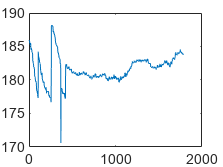

video = VideoReader('ppgMoi.mp4');
signal = zeros(1,video.NumFrames);
i=1;
while hasFrame(video)
    frame = readFrame(video);
    signal(i)=mean(frame(:,:,1),'all');
    i = i+1; 
end

plot(signal)

Calcular o ppg

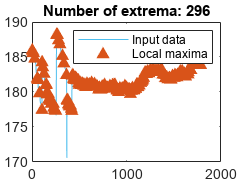

% Find local maxima
maxIndices = islocalmax(signal);

% Display results
figure
plot(signal,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on

% Plot local maxima
plot(find(maxIndices),signal(maxIndices),"^","Color",[217 83 25]/255,...
    "MarkerFaceColor",[217 83 25]/255,"DisplayName","Local maxima")
title("Number of extrema: " + nnz(maxIndices))
hold off
legend

O vídeo ta um bocado mau. Só é usavel até ao 400 o que quer que isso signifique. Vamos descobrir quanto tempo é 400:

videoframe ------ 1 s

400 ---------------- x

tempo= 400/floor(video.FrameRate)

tempo = 14.2857

ppg = floor(sum(maxIndices(1:400) == 1)*(60/tempo))

ppg = 235

damn. um bocado mau heim